# Extreme Conditions Modeling - Full Sea State Approach

Extreme conditions modeling consists of identifying the expected extreme (e.g. 100-year) response of some quantity of interest, such as WEC motions or mooring loads. 

Three different methods of estimating extreme conditions were adapted from WDRT: full sea state approach, contour approach, and MLER design wave. 

This noteboook presents the full sea state approach. 

The full sea state approach consists of the following steps: 

- Take $N$ samples to represent the sea state. Each sample represents a small area of the sea state and consists of a representative $\left(H_s \;,T_e \right)$ pair and a weight $W_i$ associated with the probability of that sea state area. 

- For each sample ${\left(H_s \;,T_e \right)}_i$ calculate the short-term (e.g. 3-hours) extreme for the quantity of interest (e.g. WEC motions or mooring tension).

- Integrate over the entire sea state to obtain the long-term extreme. This is a sum of the products of the weight of each sea state times the short-term extreme. 

See more details and equations in

[1] Coe, Ryan G., Carlos A. Michelén Ströfer, Aubrey Eckert-Gallup, and Cédric Sallaberry. 2018. “Full Long-Term Design Response Analysis of a Wave Energy Converter.” Renewable Energy 116: 356–66.

****NOTE:**** Prior to running this example it is recommended to become familiar with `environmental_contours_example.ipynb` and `short_term_extremes_example.ipynb` since some code blocks are adapted from those examples and used here without the additional description. 

## Obtain and Process NDBC Buouy Data

The first step will be obtaining the environmental data and creating the contours. See environmental_contours_example.mlx for more details and explanations of how this is being done in the following code block.

parameter = 'swden';
buoy_number = '46022';
ndbc_available_data = NDBC_available_data(parameter,"buoy_number", buoy_number);

Data request URL: https://www.ndbc.noaa.gov/data/historical/swden



% Slice the available data to only include through year 2012
rows = (ndbc_available_data.year < 2013) ;
filenames = ndbc_available_data.file(rows);

ndbc_requested_data = NDBC_request_data(parameter, filenames);

Hm0 = [];
Te = [];
for field = fieldnames(ndbc_requested_data)'
    Hm0 = [Hm0 ; significant_wave_height(ndbc_requested_data.(field{1}))];
    Te = [Te ; energy_period(ndbc_requested_data.(field{1}))];
end

% Remove Hm0 Outliers and NaNs
filter = Hm0 < 20;
Hm0 = Hm0(filter);
Te = Te(filter);
[row, ~] = find(~isnan(Te));
Hm0 = Hm0(row);
Te = Te(row);
[row, ~] = find(~isnan(Hm0));
Hm0 = Hm0(row);
Te = Te(row); 

% Delta time of sea-states in seconds 
dt = ndbc_requested_data.year_1996.time(2)- ndbc_requested_data.year_1996.time(1); 
dt= seconds(dt);

### 1. Sampling 

The first step is sampling the sea state to get samples ${\left(H_s \;,T_e \right)}_i$  and associtated weights. For this we will use the waves.contours.samples_full_seastate function.  We will sample 20 points between each return level, for 10 levels ranging from 0.001—100 years return periods. For more details on the sampling approach see:

[1] Coe, Ryan G., Carlos A. Michelén Ströfer, Aubrey Eckert-Gallup, and Cédric Sallaberry. 2018. “Full Long-Term Design Response Analysis of a Wave Energy Converter.” Renewable Energy 116: 356–66.

[2] Eckert-Gallup, Aubrey C., Cédric J. Sallaberry, Ann R. Dallman, and Vincent S. Neary. 2016. “Application of Principal Component Analysis (PCA) and Improved Joint Probability Distributions to the Inverse First-Order Reliability Method (I-FORM) for Predicting Extreme Sea States.” Ocean Engineering 112 (January): 307–19.

% Return levels
levels = [0.001, 0.01, 0.05, 0.1, 0.5, 1, 5, 10, 50, 100];

% Points per return level interval
npoints = 20;

% Create Samples
[sample_hs, sample_te, sample_weights] = samples_full_seastate(...
    Hm0, Te, npoints, levels, dt);

### 2. Short-Term Extreme Distributions

Many different methods for short-term extremes were adapted from WDRT, and a summary and examples can be found in short_term_extremes_example.mlx. The response quantity of interest is typically related to the WEC itself, e.g. maximum heave displacement, PTO extension, or load on the mooring lines. This requires running a simulation (e.g. WEC-Sim) for each of the 200 sampled sea states ${\left(H_s \;,T_e \right)}_i$. For the sake of example we will consider the wave elevation as the quantity of interest (can be thought as a proxy for heave motion in this example). Wave elevation time-series for a specific sea state can be created quickly without running any external software. 

****NOTE:**** The majority of the for loop below is simply creating the synthetic data (wave elevation time series). In a realistic case the variables `time` and `data` describing each time series would be obtained externally, e.g. through simulation software such as WEC-Sim or CFD. For this reason the details of creating the synthetic data are not presented here, instead assume for each sea state there is time-series data available. 

The last lines of the for-loop create the short-term extreme distribution from the time-series using the `loads.extreme.short_term_extreme` function. The short-term period will be 3-hours and we will use 1-hour "simulations" and the Weibul-tail-fitting method to estimate the 3-hour short-term extreme distributions for each of the 200 samples.

For more details on short-term extreme distributions see short_term_extremes_example.mlx and 

> [3] Michelén Ströfer, Carlos A., and Ryan Coe. 2015. “Comparison of Methods for Estimating Short-Term Extreme Response of Wave Energy Converters.” In OCEANS 2015 - MTS/IEEE Washington, 1–6. IEEE.

% create the short-term extreme distribution for each sample sea state
t_st = 3.0 * 60.0 * 60.0;
gamma = 3.3;
t_sim = 1.0 * 60.0 * 60.0;

ste_all = struct();

for i = 1:length(sample_hs)
    hs = sample_hs(i);
    te = sample_te(i);
    tp = te / (0.8255 + 0.03852*gamma - 0.005537*gamma^2 + 0.0003154*gamma^3);
    fprintf("Sea state %d/%d. (Hs, Te) = (%f m, %f s). Tp = %f s\n", i,length(sample_hs),hs,te,tp);
    % time & frequency arrays
    f0 = 1.0/t_sim;
    T_min = tp/10.0;  % s
    f_max = 1.0/T_min;
    Nf = floor(f_max/f0);
    time = linspace(0, t_sim, 2*Nf+1);
    f = linspace(f0, f_max, Nf);
    % spectrum
    S = jonswap_spectrum(f, tp, hs, gamma);
    % 1-hour elevation time-series
    data = surface_elevation(S, time,"seed",i);    
    % 3-hour extreme distribution 
    ste = short_term_extreme(time, data.elevation, t_st, 'peaks_weibull_tail_fit');    
    ste_all.(strcat("ste_",int2str(i))) = ste;
end

Sea state 1/200. (Hs, Te) = (3.042875 m, 10.848249 s). Tp = 12.004889 s
Sea state 2/200. (Hs, Te) = (2.403534 m, 9.200299 s). Tp = 10.181234 s
Sea state 3/200. (Hs, Te) = (2.419773 m, 9.201648 s). Tp = 10.182728 s
Sea state 4/200. (Hs, Te) = (2.495482 m, 9.189487 s). Tp = 10.169269 s
Sea state 5/200. (Hs, Te) = (2.640492 m, 9.174450 s). Tp = 10.152630 s
Sea state 6/200. (Hs, Te) = (2.594584 m, 8.869273 s). Tp = 9.814915 s
Sea state 7/200. (Hs, Te) = (2.609502 m, 8.685518 s). Tp = 9.611567 s
Sea state 8/200. (Hs, Te) = (2.512424 m, 8.077279 s). Tp = 8.938478 s
Sea state 9/200. (Hs, Te) = (2.348626 m, 8.485992 s). Tp = 9.390768 s
Sea state 10/200. (Hs, Te) = (1.874250 m, 7.465723 s). Tp = 8.261718 s
Sea state 11/200. (Hs, Te) = (2.063693 m, 8.406305 s). Tp = 9.302585 s
Sea state 12/200. (Hs, Te) = (1.753614 m, 7.913747 s). Tp = 8.757511 s
Sea state 13/200. (Hs, Te) = (2.117216 m, 8.845309 s). Tp = 9.788395 s
Sea state 14/200. (Hs, Te) = (1.396284 m, 8.195542 s). Tp = 9.069350 s
Sea state

### 3. Long-Term Extreme Distribution

Finally we integrate the weighted short-term extreme distributions over the entire sea state space to obtain the extreme distribution, assuming a 3-hour sea state coherence. For this we use the loads.extreme.full_seastate_long_term_extreme function. The integral reduces to a sum over the 200 bins of the weighted short-term extreme distributions.

lte = full_seastate_long_term_extreme(ste_all, sample_weights);

Similar to the short-term extreme functions, the output of long-term extreme function is a probability distribution. This object provides common statistical functions (PDF, CDF, PPF, etc.) and metrics (expected value, median, etc). Here, we will look at the survival function and the 100-year return level. 

The value of the survival function at a given return level (e.g. 100-years) (s_t in the code below) is $\frac{1}{N}$ where N is the number of short-term periods in the return period. In this case N is the number of 3-hour periods in a 100-year period, which gives $s_- t\approx 3e-6$. The corresponding response, i.e. the 100-year wave elevation in this case, is given as the inverse cumulative function (ppf) of 1 - s_t. This gives a 100-year wave of about 10.8 meters.  

t_st_hr = t_st/(60.0*60.0);
t_return_yr = 100.0;
s_t = 1.0/(365.25*24*t_return_yr/t_st_hr);
x_t = lte.ppf(1-s_t);

fprintf("100-year elevation: %f m \n",x_t)

100-year elevation: 10.801453 m 


Finally we plot the survival function and show the 100-year return level (dashed grey lines). The 100-year value is about 10.8 m (where the grey line intersects the x-axis)

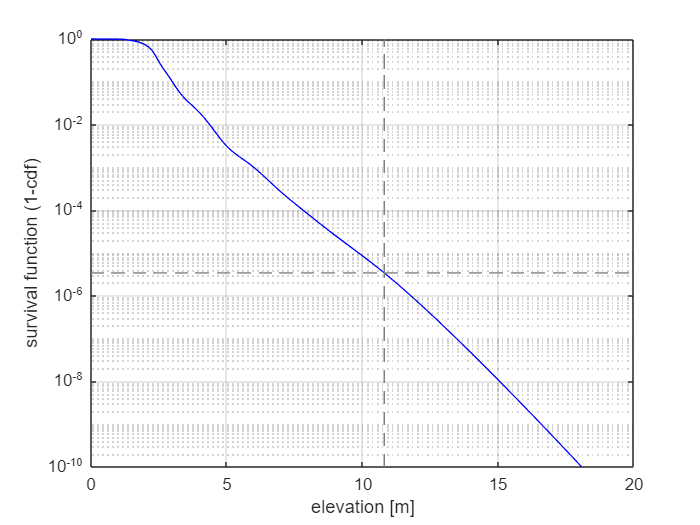

x = linspace(0, 20, 1000);
semilogy(x, lte.sf(x), 'Color', "blue")
grid on
xlabel('elevation [m]')
ylabel('survival function (1-cdf)')
xlim([0, x(end)])
y_lim = [1e-10, 1];
ylim(y_lim)

hold on
plot([0,x(end)],[s_t,s_t], '--', 'Color', "#808080")
plot([x_t,x_t], y_lim, '--', 'Color', "#808080")